# **CO61**

# Exercise 4.1

## 4.1 Part 1: 

Launched on the y axis

%initialise position and velocity
init_pos = [0,3.7]

init_pos =          0    3.7000


theta = 89.9*pi/180;
init_vel = 0.0066*[cos(theta), sin(theta)]

init_vel =     0.0000    0.0066



%define the length of the simulation and create an array of times
final_time = 500000;
t = linspace(0, final_time, final_time/10);

%calculate position of rocket
[tout, pos] = simulate_rocket(init_pos, init_vel, @r_moon_41, t);
end_time = tout(end) %as end_time<final_time, the rocket collided with the moon

end_time = 1.5697e+05

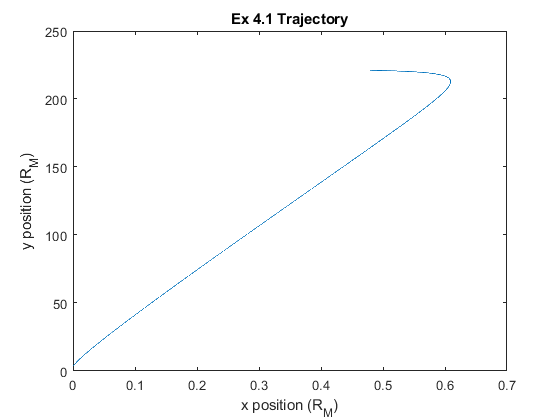


%plot x position against y position
plot(pos(:, 1), pos(:, 2))
hold on
xlabel("x position (R_M)")
ylabel("y position (R_M)")
title("Ex 4.1 Trajectory")
saveas(gcf, "Ex41-1.png")
hold off

## 4.1 Part 2: 

Finding Correct θ for launching on x axis

init_pos = [3.7,0]

init_pos =     3.7000         0



possible_theta = linspace(0, pi/2, 90); %theta values to check

final_time = 500000;
t = linspace(0, final_time, final_time/10);

for i = [1: length(possible_theta)]
    %iterate over array of theta values
    
    theta = possible_theta(i);
    init_vel = 0.0066*[cos(theta), sin(theta)];
    [tout, pos] = simulate_rocket(init_pos, init_vel, @r_moon_41, t);
    
    if norm([0, 222]-pos(end, :)) <1
        %check if rocket ended up on moon
        
        %if it did, output the theta value and plot a graph of the
        %trajectory
        theta
        plot(pos(:, 1), pos(:, 2))
        hold on
        xlabel("x position (R_M)")
        ylabel("y position (R_M)")
        title(["Trajectory of θ = " num2str(theta)])
        saveas(gcf, "Ex41-2.png")
        hold off
        break
    end
end

We find theta = 0.90012, corresponding to 51.573 degrees, works. Using `comet()`, we can plot an animation of the spacecraft's trajectory

init_pos = [3.7,0]

theta = 0.90012;
init_vel = 0.0066*[cos(theta), sin(theta)]

final_time = 500000;
t = linspace(0, final_time, final_time/10);

[tout, pos] = simulate_rocket(init_pos, init_vel, @r_moon_41, t);
end_time = tout(end) %as end_time<final_time, the rocket collided with the moon

plot(pos(:, 1), pos(:, 2))
hold on
xlabel("x position (R_M)")
ylabel("y position (R_M)")
title("Comet Trajectory for θ = 0.90012")
comet(pos(:, 1), pos(:, 2))
hold off

# Exercise 4.2

Here, we instead set `moon_pos` to `r_moon_42`, for an orbiting moon

final_time = 2000000;
t = linspace(0, final_time, final_time/10);

init_pos = [0,3.7]

init_pos =          0    3.7000


theta = 0.9101

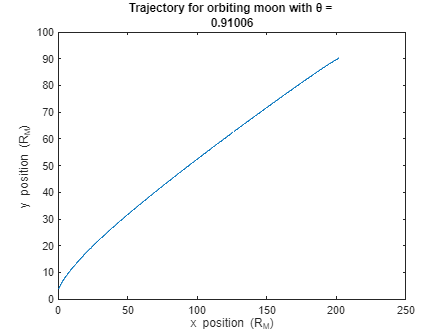


%theta values to check. Through some trial and error, I found this to be a good range to check theta values
possible_theta = linspace(50*pi/180, 55*pi/180, 50); 

for i = [1: length(possible_theta)]
    %iterate over array of theta values
    
    theta = possible_theta(i);
    init_vel = 0.0066*[cos(theta), sin(theta)];
    [tout, pos] = simulate_rocket(init_pos, init_vel, @r_moon_42, t);

    
    if norm(r_moon_42(tout(end))-pos(end, :)) <=1
        %check if rocket ended up on moon
        
        %if it did, output the theta value and plot a graph of the
        %trajectory
        theta
        plot(pos(:, 1), pos(:, 2))
        hold on
        xlabel("x position (R_M)")
        ylabel("y position (R_M)")
        title(["Trajectory for orbiting moon with θ = " num2str(theta)])
        saveas(gcf, "Ex42.png")
        hold off
        break
    end
end

tar("CO61_chri6353.tgz", ["a.m","CO61.mlx","r_moon_41.m","r_moon_42.m","simulate_rocket.m"])